%% ========================================================================
%  SIM_04_FiveSat_SwarmReconfig
%  --------------------------------------------------------------
%  - Simulates reconfiguration of 5 follower satellites into a
%    desired formation using convex optimization (CVX).
%  - Each satellite uses minimum ΔV to reach its target position.
%  - Plots both trajectories and control effort (ΔV) over time.
%
%  Author: Sabrina Nicacio
% ========================================================================

clc; clear; close all;

%% === ORBIT PARAMETERS ===
mu = 3.986e14;              % Earth's gravitational parameter (m^3/s^2)
Re = 6371e3;                % Earth radius (m)
alt = 500e3;                % Orbital altitude (m)
a = Re + alt;               % Semi-major axis (m)
n = sqrt(mu / a^3);         % Mean motion (rad/s)

T = 2*pi / n;               % Orbital period (s)
N_orbits = 1;
dt = 10;                                  % Time step (s)
N = round(N_orbits * T / dt);             % Number of time steps
t_vec = (0:N-1)*dt;

%% === SYSTEM MATRICES ===
A = [  0     0     0     1     0     0;
       0     0     0     0     1     0;
       0     0     0     0     0     1;
     3*n^2   0     0     0   2*n     0;
       0     0     0  -2*n     0     0;
       0     0  -n^2    0     0     0];

B = [zeros(3); eye(3)];

%% === INITIAL STATES AND TARGET FORMATION ===
% Define initial positions/velocities for 5 satellites
x0_list = {
    [0; 100; 0; 0; 0.1; 0],
    [0; -120; 40; 0; -0.08; 0],
    [30; 80; -50; 0; 0.05; 0],
    [-50; -90; 20; 0; -0.1; 0],
    [60; 0; -30; 0; 0; 0]
};

% Define target formation in LVLH frame (relative positions)
target_list = {
    [0; 0; 0; 0; 0; 0],
    [50; 0; 0; 0; 0; 0],
    [-50; 0; 0; 0; 0; 0],
    [0; 50; 0; 0; 0; 0],
    [0; -50; 0; 0; 0; 0]
};

num_sats = 5;
X = cell(num_sats, 1);   % Store state trajectories
U = cell(num_sats, 1);   % Store control inputs
dV_total = zeros(num_sats, 1);  % Store total DeltaV

%% === CVX OPTIMIZATION FOR EACH SATELLITE ===
for i = 1:num_sats
    x0 = x0_list{i};
    x_target = target_list{i};
    
    cvx_begin quiet
        variables x(6, N) u(3, N-1)
        minimize( sum(norms(u, 2, 1)) )
        subject to
            x(:,1) == x0;
            x(:,N) == x_target;
            for k = 1:N-1
                x(:,k+1) == x(:,k) + dt * (A * x(:,k) + B * u(:,k));
            end
    cvx_end
    
    X{i} = x;
    U{i} = u;
    dV_total(i) = sum(vecnorm(u, 2, 1));
end

%% === TOTAL DELTAV TABLE ===
sat_IDs = (1:num_sats)';
T_dV = table(sat_IDs, dV_total, ...
    'VariableNames', {'Satellite', 'DeltaV'});
disp(' ');

disp('==== Total DeltaV per Satellite ====');

==== Total DeltaV per Satellite ====


disp(T_dV);

    Satellite     DeltaV 
    _________    ________

        1          0.2086
        2         0.41161
        3         0.30244
        4        0.067024
        5         0.21239



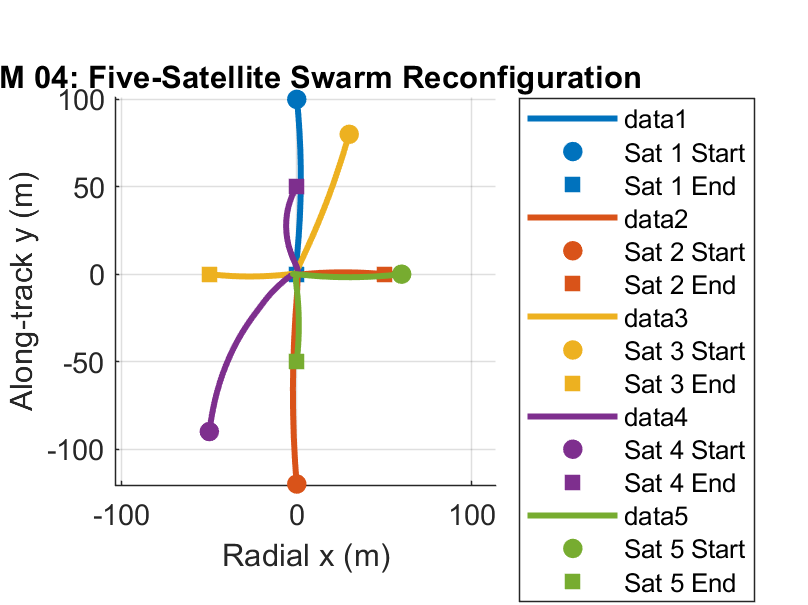


%% === PLOT 1: TRAJECTORY PLOT ===
colors = lines(num_sats);
figure; hold on;

for i = 1:num_sats
    x = X{i};
    plot(x(1,:), x(2,:), 'Color', colors(i,:), 'LineWidth', 2);
    plot(x(1,1), x(2,1), 'o', 'Color', colors(i,:), ...
        'MarkerFaceColor', colors(i,:), 'DisplayName', ['Sat ' num2str(i) ' Start']);
    plot(x(1,end), x(2,end), 's', 'Color', colors(i,:), ...
        'MarkerFaceColor', colors(i,:), 'DisplayName', ['Sat ' num2str(i) ' End']);
end

xlabel('Radial x (m)');
ylabel('Along-track y (m)');
title('SIM 04: Five-Satellite Swarm Reconfiguration');
legend('Location', 'bestoutside');
grid on; axis equal;
saveas(gcf, 'SIM_04_FiveSat_SwarmReconfig_Traj_Fixed.png');

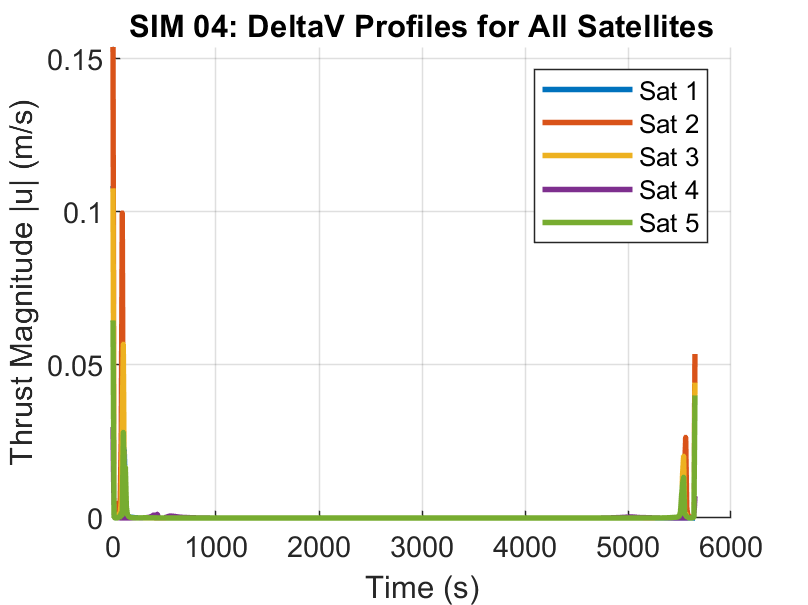


%% === PLOT 2: DELTAV PROFILES ===
figure; hold on;
for i = 1:num_sats
    u = U{i};
    dV = vecnorm(u, 2, 1);
    plot(t_vec(1:end-1), dV, 'LineWidth', 1.8, 'Color', colors(i,:));
end
xlabel('Time (s)');
ylabel('Thrust Magnitude |u| (m/s)');
title('SIM 04: DeltaV Profiles for All Satellites');
legend('Sat 1', 'Sat 2', 'Sat 3', 'Sat 4', 'Sat 5');
grid on;
saveas(gcf, 'SIM_04_FiveSat_SwarmReconfig_DeltaV.png');


%% === END ===
disp('Simulation completed: SIM_04_FiveSat_SwarmReconfig');

Simulation completed: SIM_04_FiveSat_SwarmReconfig
